# iSIM Plotting

This is a MATLAB notebook (or Live Editor file), which is similar to a jupyter notebook for python. The notebook function (Live Editor) allows you to write text in a fancier format than your already beautiflly commented code. 

`blue if your cursor is in that section). Code has a gray background. You can execute this code by using the "Run Section" button on the top right in the "Live Editor" tab. Or you can press Ctrl+Enter (in Windows).

You can use Alt+Enter to toggle between text and code. You can even insert images... like this one that shows you how to toggle between outputs below your code or outputs to the right side of your code.

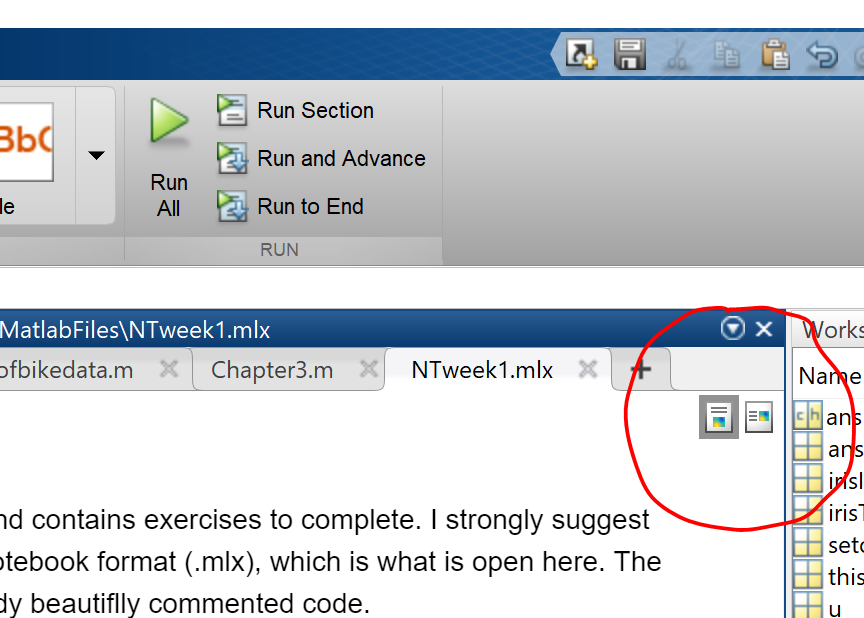

Finally, you can make a Section Break by hitting Ctrl+Alt+Enter.

Enter your calibration data into two variables.  Replace the numbers below with your values.  You will have more values than are provided below, just put spaces between each number.  Make sure you put them in order so that the first measured angle corresponds with the first measured voltage, and so on. Note that everything after the % is a MATLAB comment and does not effect the operation of the commands. 

measuredangle   = [1 2 3];            % Values for the angles
measuredvoltage = [4 5 6];            % Values for the voltages
plot(measuredvoltage,measuredangle)   % makes a plot. The first variable is the x axis

Usually, the default settings for plots are fine, but don't always look quite right for your lab report. Let's adjust the formatting a little.  Remember to fill in the title and axes labels in the commands below. Note that you can also click on the figures and edit the labels and fonts directly, but embedding the format commands in your Notebook or script file works well in case you need to regenerate the figure with new data - all the format and labels are preserved. Also if you find settings you like one week, you can copy them to the next.

h = plot(measuredvoltage,measuredangle,'bo','MarkerSize',7); % The 'bo' tells matlab to plot blue o's. Marker size controls how big the circle is
set(h,'DefaultAxesFontSize',14);                             % Sets the font to a reasonable size
xlabel('');                                                  % Sets label of x axis.  
ylabel(''); 
title('');

Now we will create the calibration curve, which you can calculate by hand using the functional form $\theta =a\left(V−V0\right)$ where V0   is the voltage measured when the pendulum angle is at rest (should be around 0.5 V). You can find the approximate slope of the line, a, by inspection of your plot.

a = 0; % Change this value
V0 = 0; % Chage this value
calibrationline = a.*( measuredvoltage-V0);                  % Calibration equation - linear relation between angle and voltage
h = plot(measuredvoltage,measuredangle,'bo','MarkerSize',7); % The 'bo' tells matlab to plot blue o's.
set(h,'DefaultAxesFontSize',14);                             % Sets the font to a reasonable size
hold on;                                                     % This puts the next thing that you plot on the same figure
plot(measuredvoltage,calibrationline,'r-','LineWidth',2);    % Plot your calibration curve as a red line
xlabel('');                                                  % Sets label of x axis.  
ylabel(''); 
title('');
hold off;                                                    % This command will make the next plot erase the current plot and start new

Now you want to save your figure. Pop it out the the notebook by mousing over the corner and hit the arrow to "Open in figure window".

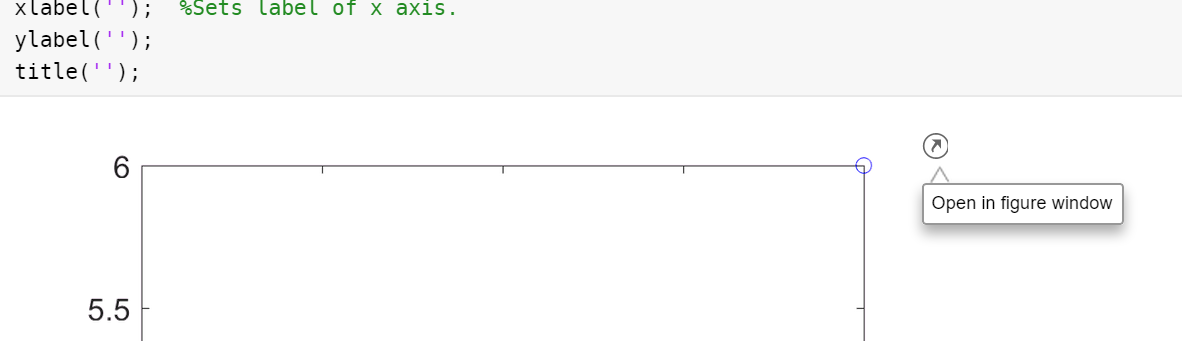

Click File -> Save As and then save your figure as a .jpg or .png (which makes it easy to input into your report.

# Creating your second figure.

To create your second plot, which should show angle over time of your recorded pendulum dynamics. To do this, you first need to load your data.

The easiest way to do this is to use the Import Data button (on the Home tab). 

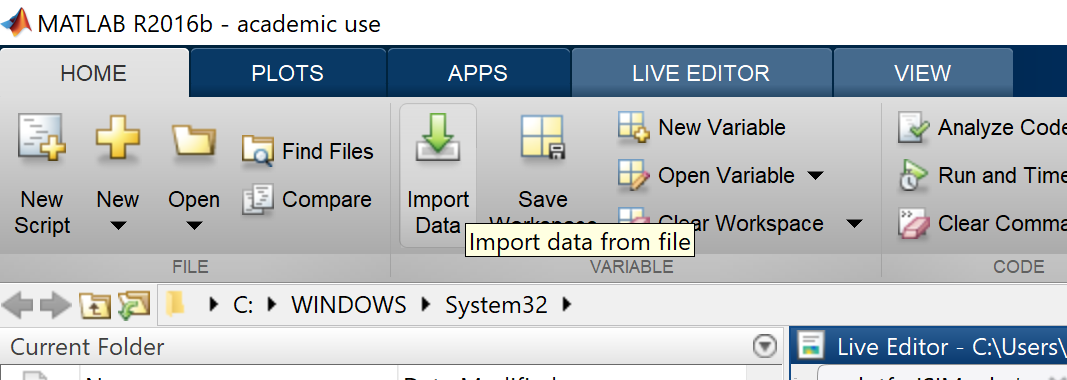

Select the file that you recorded from your Analog Discovery. This should be a comma separated file (.csv). Make sure your data is highlighed and then click the Import Selection button in the top right. Change the "output type" to "column vectors" - the default for you may be "table". 

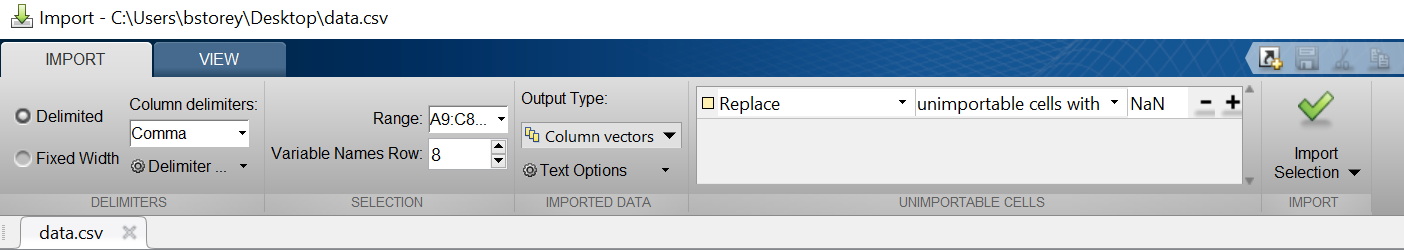

You should now have some new variables in your workspace (in addition to measuredangle, measuredvoltage, and h). You can see this in the Workspace window or by running the command "whos" in this script (or in the Command Window).

whos

One variable should be named Times (these are the recording times). The other variable is probably named Channel1V (or something similar).  Chanel1V are the voltages at those times.

You can plot your data to make sure that it makes sense.  You may need to change the variable names.

h = plot(Times,Channel1V);            % plots the experimental data from the csv file
set(h,'DefaultAxesFontSize',14);      % Sets the font to a reasonable size
xlabel('Time (s)');                   % Sets label of x axis.  Confirm the time is in seconds, or change the label 
ylabel('Channel 1 Voltage (Volts)'); 
title('Raw voltage over time');

Now you are going to create a new plot (your actual second plot) of angle over time.  To do this, you need to convert the voltage values to angle values. Luckily, you just came up with an equation to do this.  Make a new variable called angleovertime that converts and values in Channel1V to angles.

theta = Channel1V; %This equation need to be changed by you.

% Put code in here to generate a new plot of time and angle and labels



Don't forget to save this new figure too.